# Choose types based on logged values from simulation data

To choose types based on logged values from simulation data:

- Turn on logging with \texttt{buildInstrumentedMex} in the test script.

- Run simulated data through the generated \matlab executable (MEX) files.

- Inspect the logged values from the plots and report generated by `VisualizeDatatypes` in the test script.

- Choose types based on the proposed types in the *Instrumentation Report Viewer*.

Types proposed from simulation data only reflect the quality of test inputs. Unless you can guarantee that the inputs represent all possible cases, then they are like the Pirate's Code —they're more like guidelines than actual rules.

For feed-forward linear systems, like an FIR filter, the limits are easily tested, so choosing types based on logged values from simulation data is a viable approach.

## Full Range Test Inputs

Good test inputs for any algorithm should test both that the algorithm produces expected results, and also push the output to the limits.

Assuming that the input is in the range $-1 \leq x \leq 1$, you can force an FIR filter to achieve its maximum gain by using an input of $+1$ and $-1$ that matches the sign of its coefficients.  

You can see the maximum gain $1.4305$ achieved in the right side of the following plot.

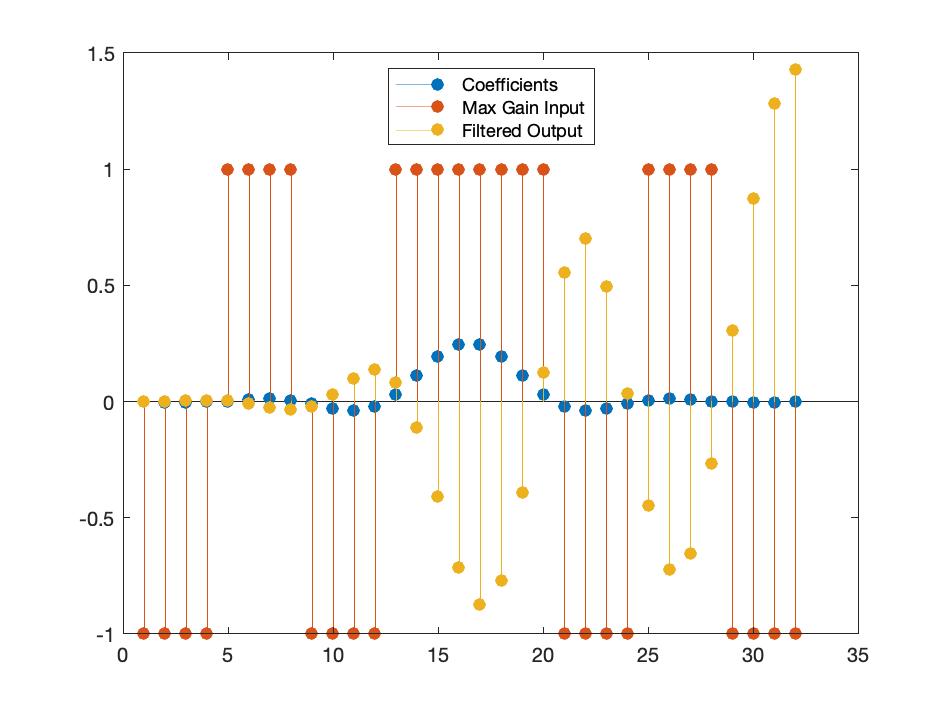

b = fir_filter_inputs;
x = sign(fliplr(b));
y = filter(b,1,x);
stem([b;x;y]','filled');
legend('Coefficients','Max Gain Input','Filtered Output','Location','north')

 max_gain = norm(b,1) 

max_gain =    1.430487966674604


The flip left-right (`fliplr`) in the code above is because the $n$th input $x(n)$ is multiplied by the first coefficient $b(1)$, the previous input $x(n-1)$ by the second coefficient $b(2)$, and so forth, as seen in the difference equation.


$$y(n) = b(1)x(n) + b(2)x(n-1) + b(3)x(n-2) \cdots + b(\textrm{end})x(n-\textrm{length}(b)+1).$$
